clc,clear,close all

% f: 函数
f = @(x) 1./(1+25*x.^2);

% x: 插值点
x = -1:0.2:1;     %注意，这里 x_train 应该输入一个行向量

% y: 插值点处的函数值
y = f(x);

% xx: 要预测的点
xx = -1:0.01:1;

% y: 预测的函数值
yy = newton_interpolation(x,y,x);

% y_real: 真实的函数值
y_real = f(x);

% interpolation_error: 误差. F 范数
interpolation_error = norm(y_real-yy);

% 输出结果
disp('插值拟合结果为')

插值拟合结果为


disp(y)

    0.0385    0.0588    0.1000    0.2000    0.5000    1.0000    0.5000    0.2000    0.1000    0.0588    0.0385



disp('真实值为')

真实值为


disp(y_real)

    0.0385    0.0588    0.1000    0.2000    0.5000    1.0000    0.5000    0.2000    0.1000    0.0588    0.0385



disp('误差为')

误差为


disp(interpolation_error)

   6.9200e-14



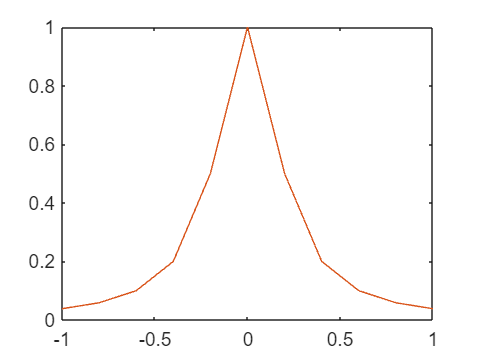

plot(x,y)
hold on
plot(x,y_real)